**Instrukcja do ćwiczeń laboratoryjnych:**

**Regresja i interpolacja danych z analogowego czujnika odległości**

**Wstęp**

W ćwiczeniach tych należy wykonać kalibrację analogowego czujnika odległości, używając różnych metod dostępnych w MATLAB. Celem jest przekształcenie sygnału analogowego z czujnika na odpowiadającą mu odległość za pomocą metod interpolacji i dopasowania krzywych.

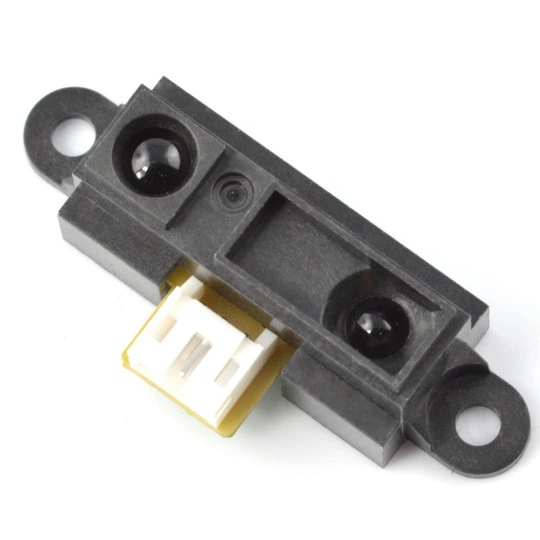    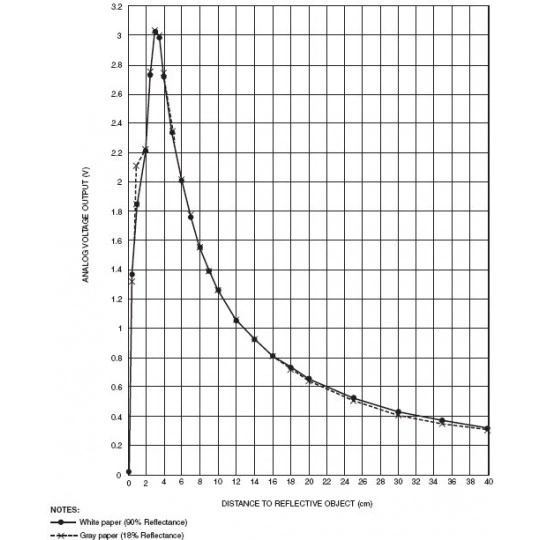 

Zdjecie oraz charaktersytyka U = f(x) czujnika odległości wykorzystanego podczas ćwiczeń laboratoryjnych.

**2. Wymagania wstępne**

Przed przystąpieniem do ćwiczeń:

- Zapoznaj się z działaniem czujników analogowych i zasady kalibracji.

- Nalezy wykorzystać mikrokontroler Arduino (jedno z wejść analogowych) i analogowy czujnik odległosci do uzyskania danych wejśiowych do laboratorium. Należy zainstalować bibliotekę do Arduino UNO.

- W MATLAB przejdź do **Home > Add-Ons > Get Hardware Support Packages**.

- Wyszukaj i zainstaluj **MATLAB Support Package for Arduino Hardware**.

Upewnij się, że:

- Arduino jest podłączone do komputera za pomocą USB.

- Wiesz, na którym porcie szeregowym (np. `COM3`) znajduje się Arduino.

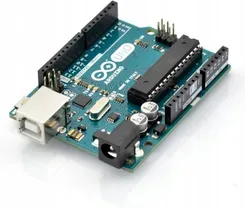

Zdjecia mikrokontrolera Arduino UNO. 

% Tworzenie obiektu Arduino
a = arduino('COM3', 'Uno'); % Zmień 'COM3' na odpowiedni port COM

% Odczyt z wejścia analogowego A0
analogPin = 'A0'; % Ustawienie pinu analogowego
for i = 1:10 % Przykładowa pętla odczytu 10 próbek
    analogValue = readVoltage(a, analogPin); % Odczyt napięcia (0-5V)
    fprintf('Analog value from %s: %.2f V\n', analogPin, analogValue);
    pause(0.5); % Odstęp czasowy między odczytami
end

% Zwolnienie zasobów Arduino
clear a;

**3. Przygotowanie danych kalibracyjnych**

Najpierw wprowadź dane kalibracyjne z czujnika. Wartości te można uzyskać, mierząc odległości przy określonych sygnałach wyjściowych z czujnika.

% Przykładowe dane kalibracyjne
analog_values = [0.1, 0.2, 0.3, 0.4, 0.5 0.6 0.7 0.8 0.9 1.0 1.1 1.2 1.3 1.4]; % sygnał analogowy
distances =     [4, 22, 31, 37, 55, 66, 77, 88, 99, 110, 105, 120, 130, 140 ]; % rzeczywiste odległości w cm

**4. Dopasowanie wielomianowe (funkcje **`polyfit`** i **`polyval`**)**

Dopasowanie wielomianowe polega na znalezieniu wielomianu, który najlepiej opisuje zależność między sygnałem analogowym a odległością.

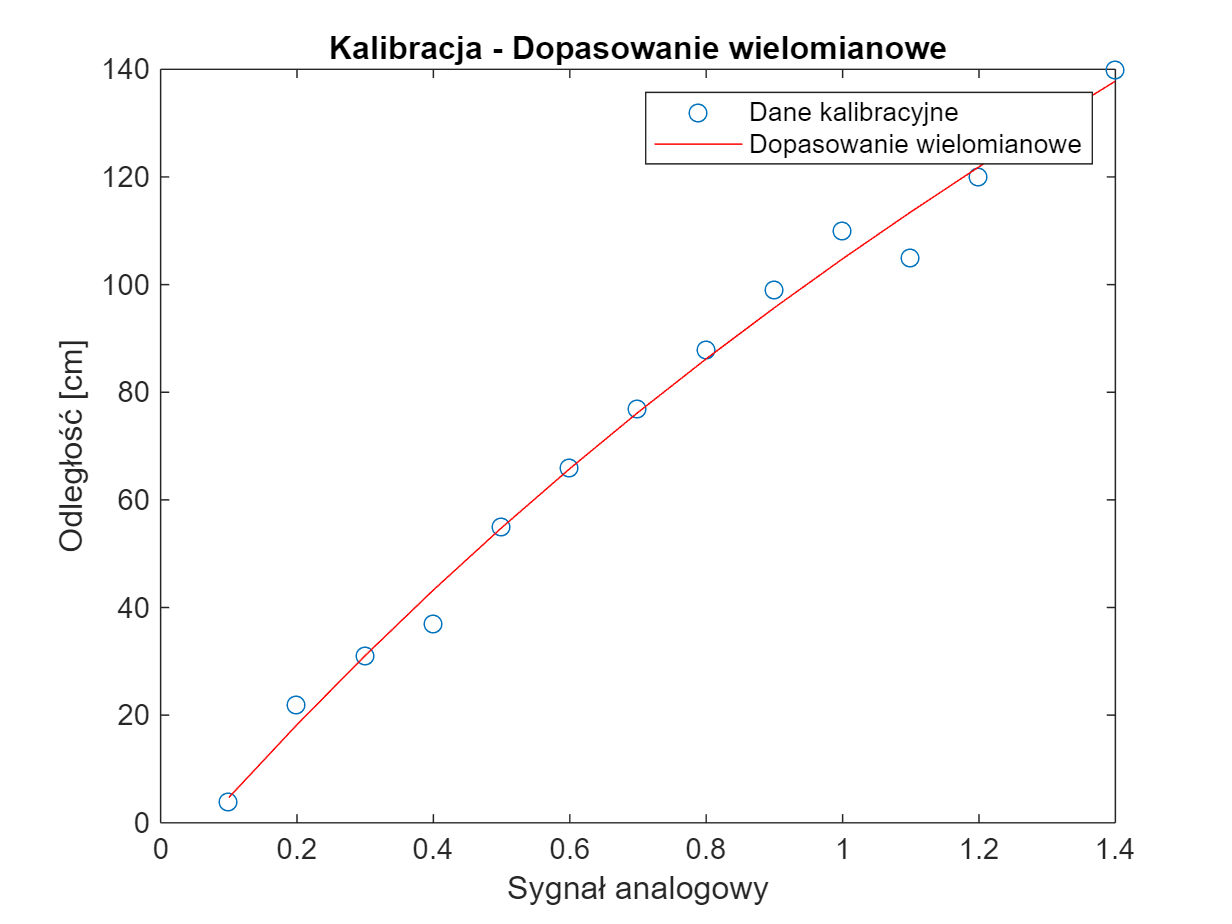

% Dopasowanie wielomianu stopnia 2
degree = 3;
p = polyfit(analog_values, distances, degree);
calibrated_distances_poly = polyval(p, analog_values);


% Wyświetlenie wyników
figure;
plot(analog_values, distances, 'o', 'DisplayName', 'Dane kalibracyjne');
hold on;
plot(analog_values, calibrated_distances_poly, '-r', 'DisplayName', 'Dopasowanie wielomianowe');
title('Kalibracja - Dopasowanie wielomianowe');
xlabel('Sygnał analogowy');
ylabel('Odległość [cm]');
legend;
hold off;

**5. Interpolacja liniowa (funkcja **`interp1`**)**

Interpolacja liniowa polega na oszacowaniu wartości odległości między punktami kalibracyjnymi.

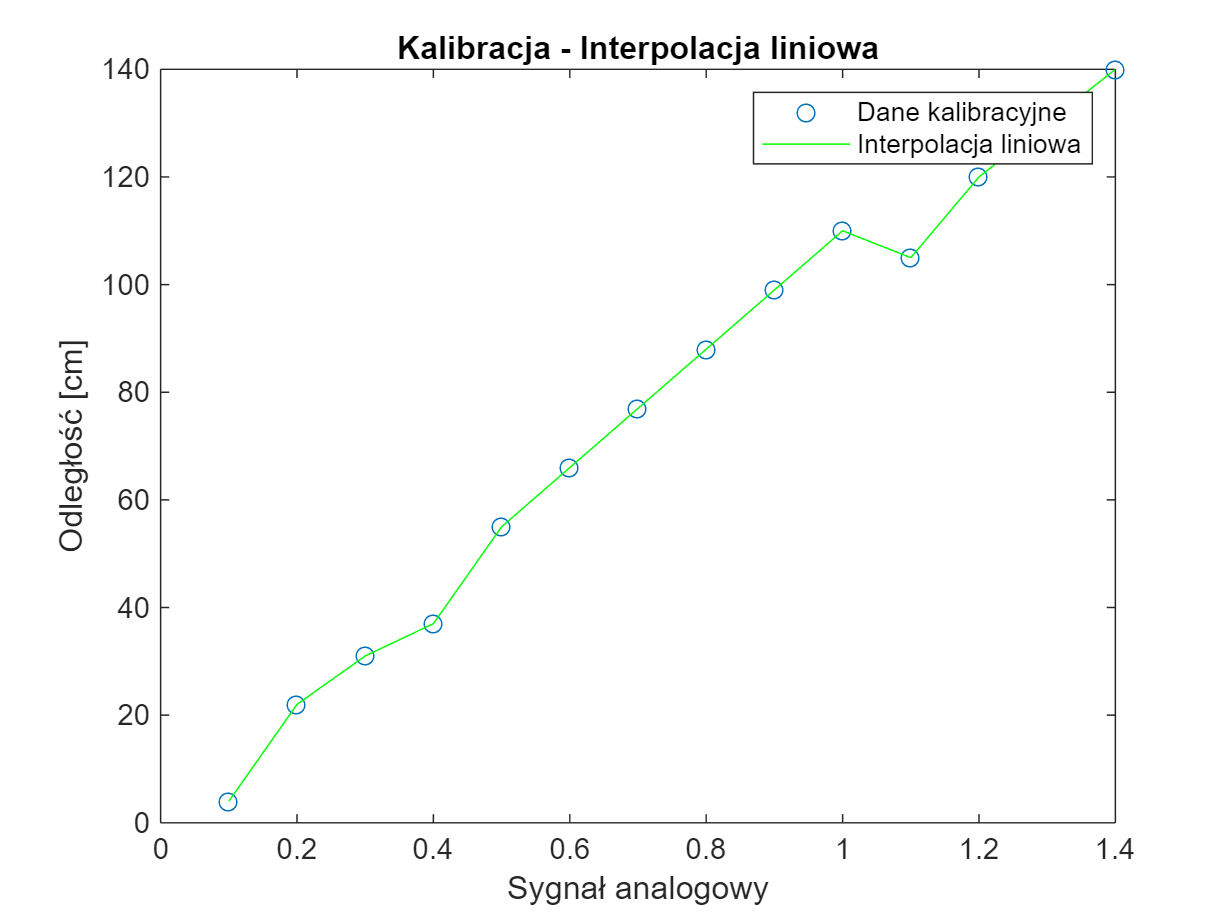

% Interpolacja liniowa
calibrated_distances_interp = interp1(analog_values, distances, analog_values, 'linear');
% Wyświetlenie wyników

figure;
plot(analog_values, distances, 'o', 'DisplayName', 'Dane kalibracyjne');
hold on;
plot(analog_values, calibrated_distances_interp, '-g', 'DisplayName', 'Interpolacja liniowa');
title('Kalibracja - Interpolacja liniowa');
xlabel('Sygnał analogowy');
ylabel('Odległość [cm]');
legend;
hold off;

**6. Dopasowanie nieliniowe (funkcja **`fit`**)**

Funkcja `fit` umożliwia dopasowanie funkcji nieliniowych, co może być użyteczne, gdy charakterystyka czujnika nie jest liniowa. Wymaga ona pakietu Curve Fitting Toolbox.

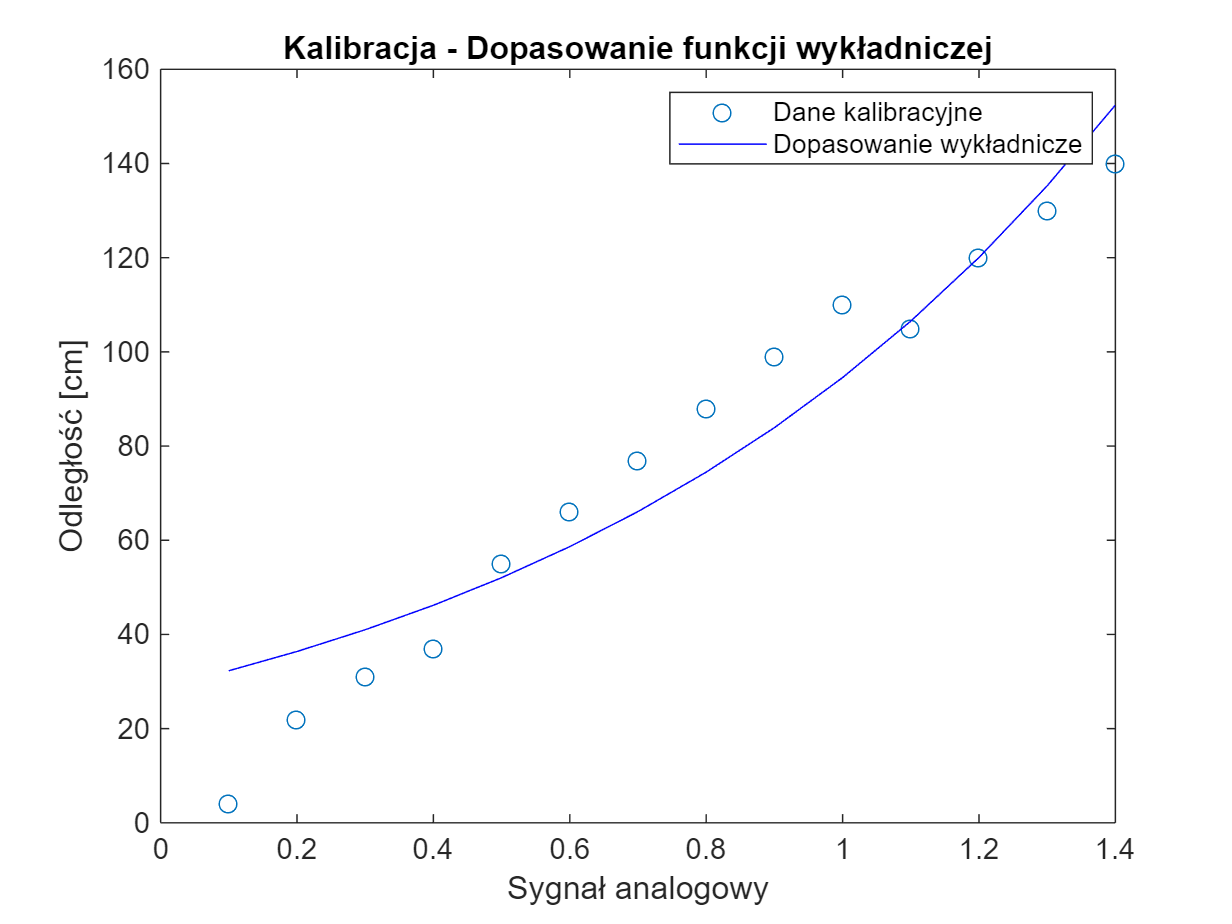

% Dopasowanie funkcji wykładniczej
f = fit(analog_values', distances', 'exp1');
calibrated_distances_fit = f(analog_values);

% Wyświetlenie wyników
figure;
plot(analog_values, distances, 'o', 'DisplayName', 'Dane kalibracyjne');

hold on;
plot(analog_values, calibrated_distances_fit, '-b', 'DisplayName', 'Dopasowanie wykładnicze');
title('Kalibracja - Dopasowanie funkcji wykładniczej');
xlabel('Sygnał analogowy');
ylabel('Odległość [cm]');
legend;
hold off;

**7. Analiza wyników**

Należy porównać wyniki uzyskane dla różnych metod kalibracji. Przeanalizuj, która metoda daje najlepsze wyniki, i uzasadnij wybór.

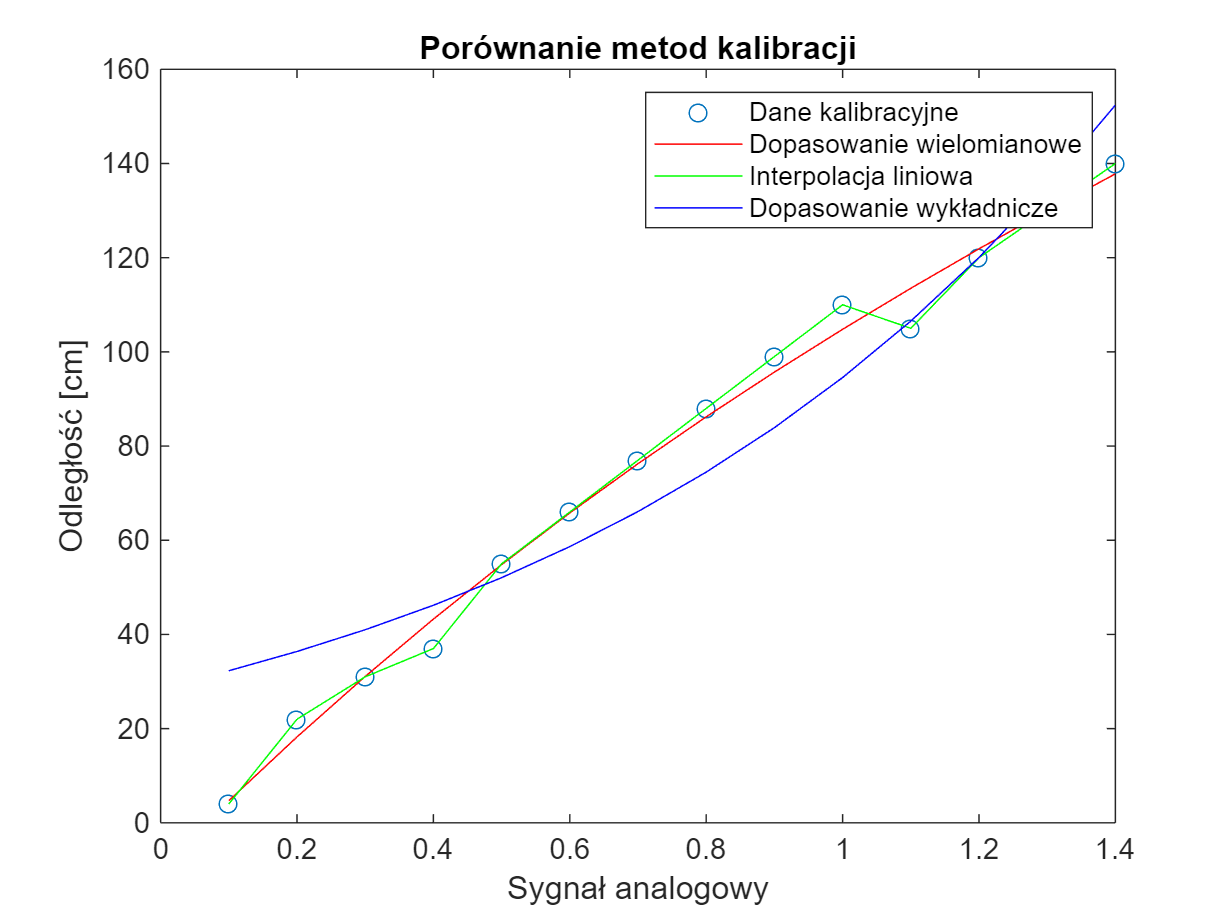

% Wykres porównawczy dla wszystkich metod
figure;
plot(analog_values, distances, 'o', 'DisplayName', 'Dane kalibracyjne');
hold on;
plot(analog_values, calibrated_distances_poly, '-r', 'DisplayName', 'Dopasowanie wielomianowe');
plot(analog_values, calibrated_distances_interp, '-g', 'DisplayName', 'Interpolacja liniowa');
plot(analog_values, calibrated_distances_fit, '-b', 'DisplayName', 'Dopasowanie wykładnicze');

title('Porównanie metod kalibracji');
xlabel('Sygnał analogowy');

distance = 125.9584

ylabel('Odległość [cm]');
legend;
hold off;

Jak wyznaczyć wartość odległości na podstawie zmierzonego napięcia znająć charakterystykę czujnika? 

distance = polyval(p, 1.25)

**Podczas ćwiczeń laboratoryjnych:**

Należy przeanalizwoać uzyskane wyniki, wskazując, która metoda kalibracji jest najdokładniejsza i najlepiej odwzorowuje rzeczywistość.

Wykonać aplikację do dynamicznej wizualizacji odległości i/lub wyświetlania wyskalowanej wartości. 